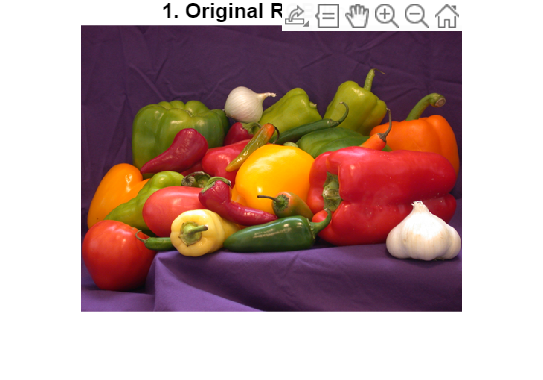

clear all;
close all;
clc;

originalImage = imread('peppers.png');

if size(originalImage, 3) ~= 3
    error('Please provide a color (RGB) image');
end

hsvImage = rgb2hsv(originalImage);
ycbcrImage = rgb2ycbcr(originalImage);

V_channel = hsvImage(:,: ,3);
V_enhanced = adapthisteq(V_channel, 'ClipLimit', 0.02, 'Distribution', 'rayleigh');

hsvEnhanced = hsvImage;
hsvEnhanced(:,:,3) = V_enhanced;

enhancedImage = hsv2rgb(hsvEnhanced);
enhancedImage = im2uint8(enhancedImage);

noisyImage = imnoise(enhancedImage, 'salt & pepper', 0.02);

restoredImage = zeros(size(noisyImage), 'uint8');
for i = 1:3
    restoredImage(:,:,i) = medfilt2(noisyImage(:,:,i), [3 3]);
end

hsvRestored = rgb2hsv(restoredImage);

H = hsvRestored(: ,:,1);
S = hsvRestored(:,:,2);
V = hsvRestored(: ,:,3);

redMask1 = (H >= 0 & H <= 0.05) & (S >= 0.4) & (V >= 0.3);
redMask2 = (H >= 0.95 & H <= 1) & (S >= 0.4) & (V >= 0.3);
segmentedMask = redMask1 | redMask2;

segmentedImage = zeros(size(restoredImage), 'uint8');
for i = 1:3
    channel = restoredImage(:,:,i);
    channel(~segmentedMask) = 0;
    segmentedImage(:,:,i) = channel;
end

se = strel('disk', 5);

openedMask = imopen(segmentedMask, se);
closedMask = imclose(openedMask, se);
finalMask = imdilate(closedMask, strel('disk', 2));
finalMask = imfill(finalMask, 'holes');

morphImage = zeros(size(restoredImage), 'uint8');
for i = 1:3
    channel = restoredImage(:,:,i);
    channel(~finalMask) = 0;
    morphImage(: ,:,i) = channel;
end

figure(1);
imshow(originalImage);
title('1. Original RGB Image');

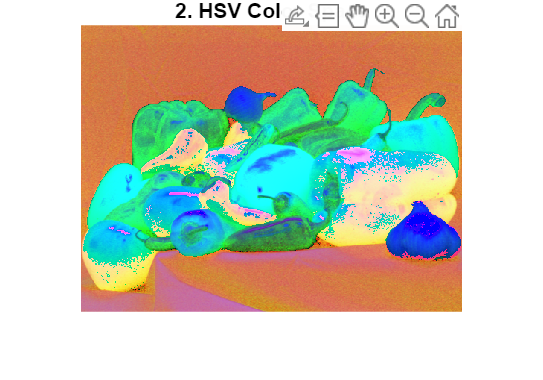


figure(2);
imshow(hsvImage);
title('2. HSV Color Space');

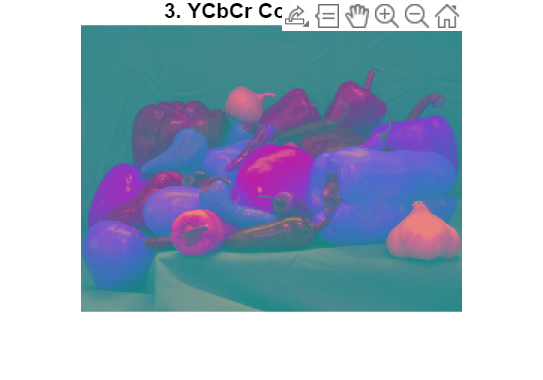


figure(3);
imshow(ycbcrImage);
title('3. YCbCr Color Space');

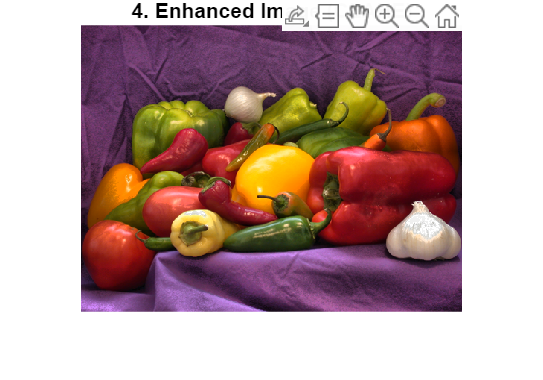


figure(4);
imshow(enhancedImage);
title('4. Enhanced Image (CLAHE)');

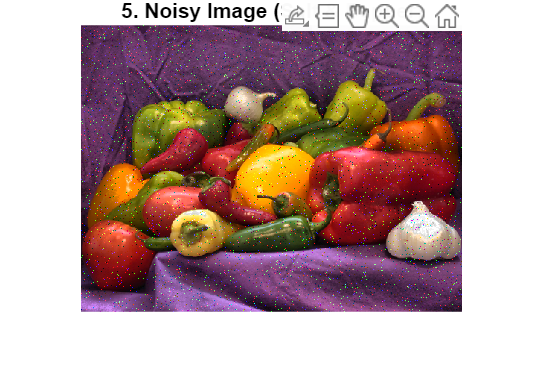


figure(5);
imshow(noisyImage);
title('5. Noisy Image (Salt & Pepper)');

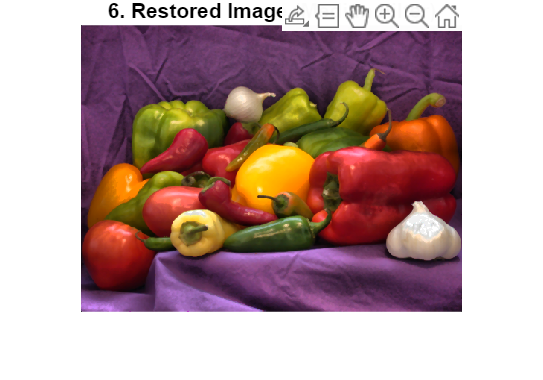


figure(6);
imshow(restoredImage);
title('6. Restored Image (Median Filter)');

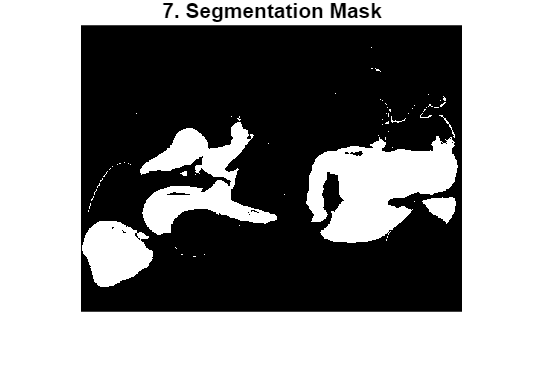


figure(7);
imshow(segmentedMask);
title('7. Segmentation Mask');

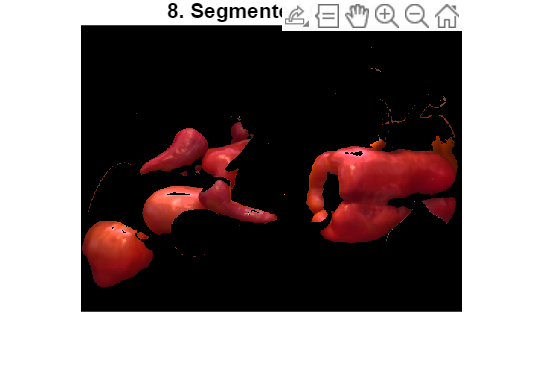


figure(8);
imshow(segmentedImage);
title('8. Segmented Output');

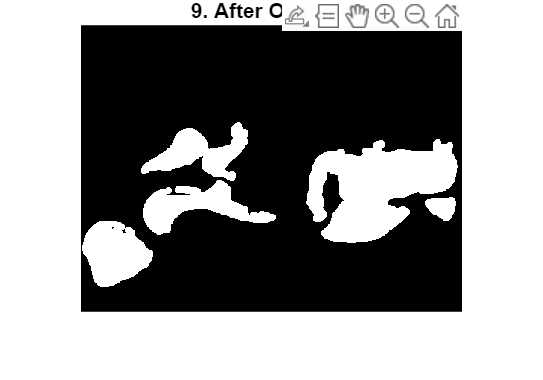


figure(9);
imshow(openedMask);
title('9. After Opening');

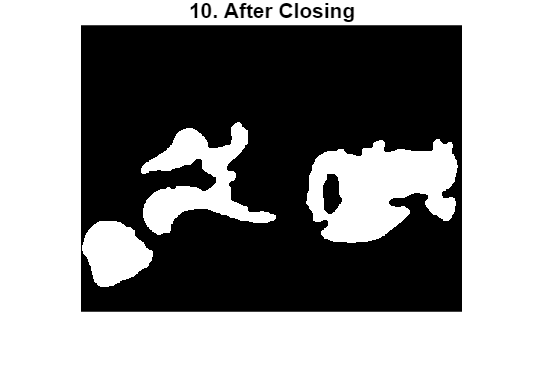


figure(10);
imshow(closedMask);
title('10. After Closing');

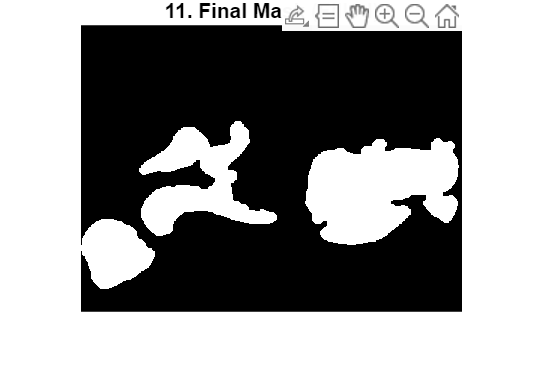


figure(11);
imshow(finalMask);
title('11. Final Mask (Filled)');

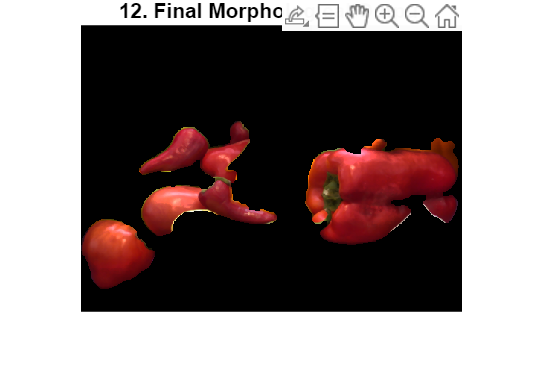


figure(12);
imshow(morphImage);
title('12. Final Morphological Output');

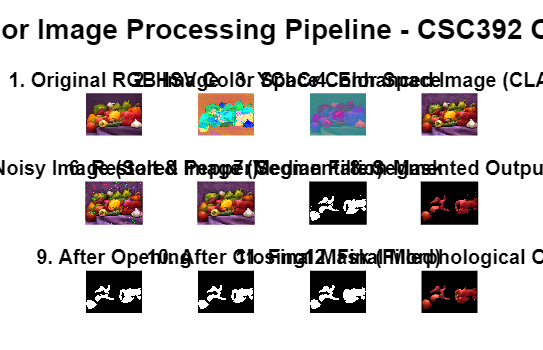


figure(13);
set(gcf, 'Name', 'Digital Image Processing Pipeline', 'NumberTitle', 'off');
set(gcf, 'Position', [50 50 1400 900]);

subplot(3, 4, 1);
imshow(originalImage);
title('1. Original RGB Image', 'FontSize', 10, 'FontWeight', 'bold');

subplot(3, 4, 2);
imshow(hsvImage);
title('2. HSV Color Space', 'FontSize', 10, 'FontWeight', 'bold');

subplot(3, 4, 3);
imshow(ycbcrImage);
title('3. YCbCr Color Space', 'FontSize', 10, 'FontWeight', 'bold');

subplot(3, 4, 4);
imshow(enhancedImage);
title('4. Enhanced Image (CLAHE)', 'FontSize', 10, 'FontWeight', 'bold');

subplot(3, 4, 5);
imshow(noisyImage);
title('5. Noisy Image (Salt & Pepper)', 'FontSize', 10, 'FontWeight', 'bold');

subplot(3, 4, 6);
imshow(restoredImage);
title('6. Restored Image (Median Filter)', 'FontSize', 10, 'FontWeight', 'bold');

subplot(3, 4, 7);
imshow(segmentedMask);
title('7. Segmentation Mask', 'FontSize', 10, 'FontWeight', 'bold');

subplot(3, 4, 8);
imshow(segmentedImage);
title('8. Segmented Output', 'FontSize', 10, 'FontWeight', 'bold');

subplot(3, 4, 9);
imshow(openedMask);
title('9. After Opening', 'FontSize', 10, 'FontWeight', 'bold');

subplot(3, 4, 10);
imshow(closedMask);
title('10. After Closing', 'FontSize', 10, 'FontWeight', 'bold');

subplot(3, 4, 11);
imshow(finalMask);
title('11. Final Mask (Filled)', 'FontSize', 10, 'FontWeight', 'bold');

subplot(3, 4, 12);
imshow(morphImage);
title('12. Final Morphological Output', 'FontSize', 10, 'FontWeight', 'bold');

sgtitle('Color Image Processing Pipeline - CSC392 OEL', 'FontSize', 14, 'FontWeight', 'bold');